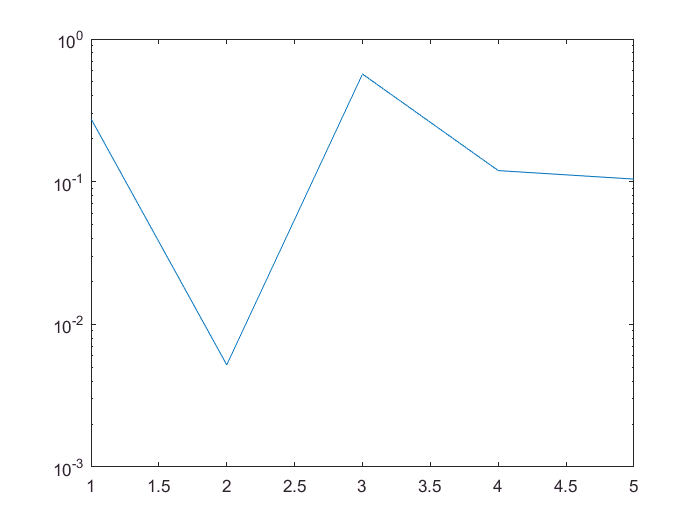

%
i=input('\n No. of iterations? ');
omega_0=input('\n angular frequency omega_0 (rad/s)? ');
thetao=input('\n angle of arrival, theta_o (degrees)? ');
thetao=pi*thetao/180;
deltao=pi*sin(thetao); %diffrence between arrival time of jammer at A & B
sigma_a=input('\n Variance of the desired signal, sigma_alpha? ');
sigma_b=input('\n Variance of jammer signal, sigma_beta? ');
 mu=0.3;
 xi=zeros(i,1);
 runs=input('\n \n No. of runs (for ensemble averaging)? ');%
for k=1:runs
 a=sqrt(sigma_a)*randn(i,1); %desired signal
 b=sqrt(sigma_b)*randn(i,1); %jammer
 theta_a=2*pi*rand; %randon phase for desired signal
 theta_b=2*pi*rand; %random phase for jammer

 % "xp" is the signal picked up at the primary.

 xp=a.*cos([1:i]'*omega_0+theta_a)+b.*cos([1:i]'*omega_0-deltao+theta_b);

 % "x1" and "x2" are the signals at the reference taps.

 x1=a.*cos([1:i]'*omega_0+theta_a)+b.*cos([1:i]'*omega_0+theta_b);
 x2=a.*sin([1:i]'*omega_0+theta_a)+b.*sin([1:i]'*omega_0+theta_b);
 w=[0 0]';

 for n=1:i
 xtdl=[x1(n); x2(n)];
 e=xp(n)-w'*xtdl;
 w=w+2*mu*e*xtdl;
 xi(n)=xi(n)+e^2;
 end
end
xi=xi/runs;
figure(1); semilogy(xi)

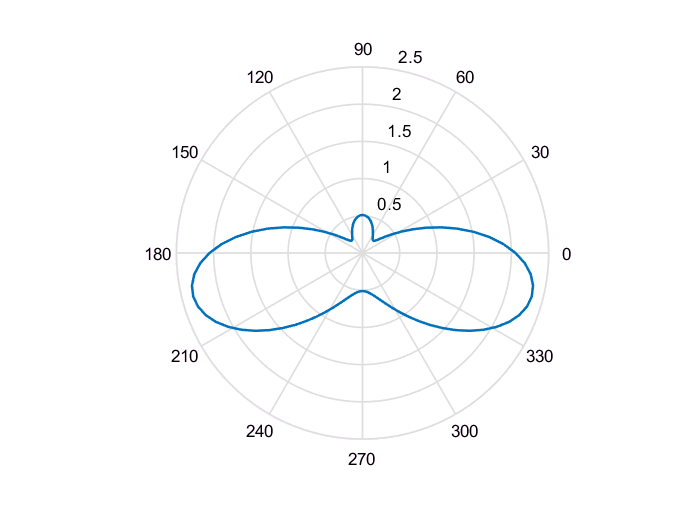

theta=2*pi*[0:0.01:1];
gain=(cos(pi*sin(theta))-w(1)).^2+(sin(pi*sin(theta))-w(2)).^2;
figure(2);
f=polar(theta,gain);
set(f,'LineWidth',1.5)